# Pre-lab A: Ploting Random Noise

## Exercise 1 

## Create a line on the 2D plane.

Recall a line on a 2D plane can be defined by **only** two variables in the form of  $y=\textrm{ax}+b$. This form illustrates all the lines except the vertical ones, e.g. $x=3$. Of note, one may use the general form of $\textrm{Ax}+\textrm{By}=C$, but it still has two variables if $B\not= 0$ because it is equivalent to $\frac{A}{B}x+\frac{B}{B\;}y=\frac{C}{B}$. In this problem, we draw a line using the first approach and a random slop limited to the range of (-2.5 , -0.5). The line passes from point$\left(0\ldotp 0,1\ldotp 0\right)$. For this end, we use *rand()* function that generates a uniformally random number within the interval of $\left(0,1\right)$and apply a linear transformation (i.e. multiplication and a summation) to its output. We then finally add $b$:

b = 1.0;                      % line passes the origin 
a = -2 * rand()  - 0.5      % creating a random slop

a = -0.6241

Creating a line using vectors

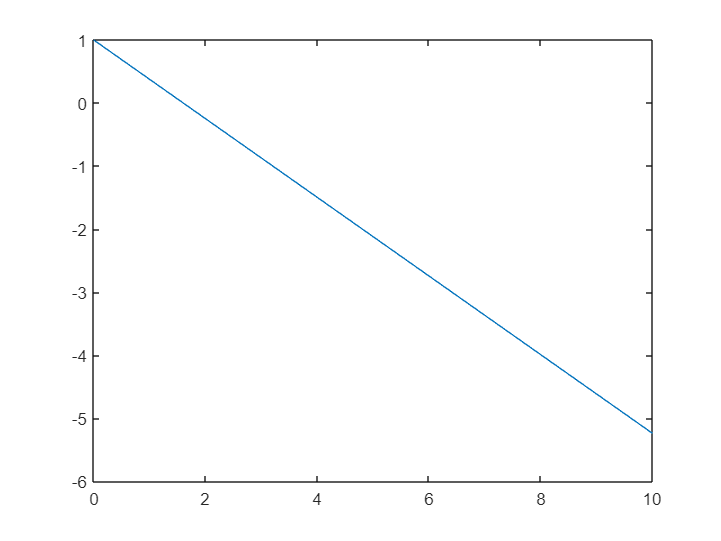

N = 50;                     % numbr of points using to demonstrate a line
x = linspace(0, 10, 50);    
y = a * x + b;
clf reset                 % clearing the Figure
plot(x, y)

Everything in MATLAB is a matrix...

## Exercise 2

In this exercise, we want to create $N$ random points and scatter them onto the rectangle of $x\in \left(0\ldotp 75\;,2\ldotp 25\right)\;y\in \left(2\ldotp 75,5\ldotp 25\right)$using *rand()* with dual input:

rand(2,3)       % example for rand with two inputs

ans =     0.2982    0.5054    0.6311
    0.0464    0.7614    0.0899


## Part 1

N = 50;
x  = rand(1, N)

x =     0.0809    0.7772    0.9051    0.5338    0.1092    0.8258    0.3381    0.2940    0.7463    0.0103    0.0484    0.6679    0.6035    0.5261    0.7297    0.7073    0.7814    0.2880    0.6925    0.5567    0.3965    0.0616    0.7802    0.3376    0.6079    0.7413    0.1048    0.1279    0.5495    0.4852    0.8905    0.7990    0.7343    0.0513    0.0729    0.0885    0.7984    0.9430    0.6837    0.1321    0.7227    0.1104    0.1175    0.6407    0.3288    0.6538    0.7491    0.5832    0.7400    0.2348


y= rand(1, N)

y =     0.7350    0.9706    0.8669    0.0862    0.3664    0.3692    0.6850    0.5979    0.7894    0.3677    0.2060    0.0867    0.7719    0.2057    0.3883    0.5518    0.2290    0.6419    0.4845    0.1518    0.7819    0.1006    0.2941    0.2374    0.5309    0.0915    0.4053    0.1048    0.1123    0.7844    0.2916    0.6035    0.9644    0.4325    0.6948    0.7581    0.4326    0.6555    0.1098    0.9338    0.1875    0.2662    0.7978    0.4876    0.7690    0.3960    0.2729    0.0372    0.6733    0.4296


Let's move our random horizontal locations (x) to the desired range, using a linear transformation:

x= x * 1.5 + 0.75

x =     0.8713    1.9159    2.1077    1.5507    0.9137    1.9887    1.2571    1.1910    1.8695    0.7655    0.8227    1.7519    1.6552    1.5392    1.8446    1.8109    1.9221    1.1820    1.7888    1.5850    1.3448    0.8424    1.9203    1.2564    1.6618    1.8619    0.9072    0.9418    1.5743    1.4778    2.0857    1.9484    1.8515    0.8270    0.8593    0.8828    1.9475    2.1645    1.7756    0.9481    1.8341    0.9155    0.9262    1.7111    1.2432    1.7307    1.8737    1.6248    1.8600    1.1022


y= y * 2.5 + 2.75  % .... your code here ... %

y =     4.5874    5.1765    4.9173    2.9656    3.6661    3.6730    4.4626    4.2449    4.7234    3.6691    3.2651    2.9667    4.6798    3.2642    3.7207    4.1294    3.3224    4.3549    3.9612    3.1296    4.7048    3.0015    3.4852    3.3434    4.0772    2.9787    3.7633    3.0121    3.0307    4.7111    3.4789    4.2588    5.1611    3.8312    4.4869    4.6452    3.8316    4.3887    3.0244    5.0844    3.2187    3.4154    4.7446    3.9690    4.6724    3.7400    3.4323    2.8431    4.4332    3.8239


Now we plot them:

scatter(x, y, 'filled')
xlabel('X')
ylabel('Y')
hold on

## Part 2

In this part, we want to find what percent of *N* points inside the inner green rectangle of $x\in \left(1\ldotp 0\;,2\ldotp 0\right)\;y\in \left(3\ldotp 0,5\ldotp 0\right)$. We shall do so without and with a *for* loop. The former is:

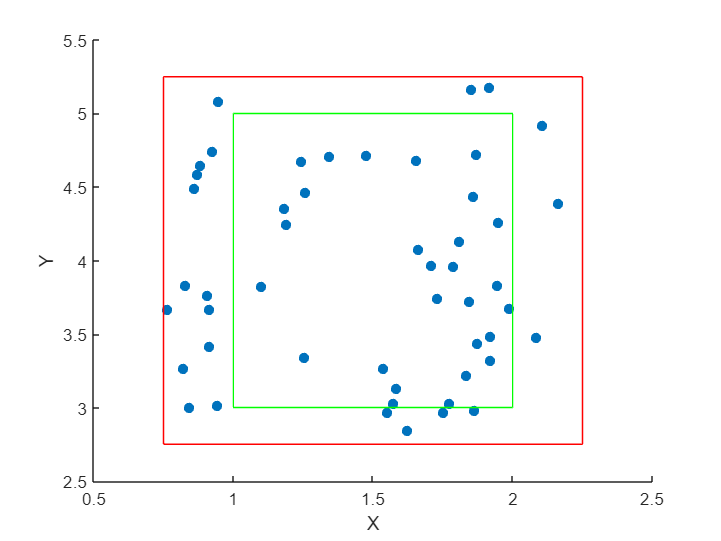

rectangle('Position', [1.0 3.0 1.0 2.0] ,  "EdgeColor",'g');
rectangle('Position', [0.75 2.75 1.5 2.5], "EdgeColor",'r')
hold off

Now we mark all the indices of vector *x* within the horizontal range of the green rectangle.

x_to_delete = x < 1.0   |   x > 2.0

x_to_delete = 1×50 logical array
   1   0   1   0   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   1   0   0   1   0   0   1   1   1   0   1   0   1   0   1   1   0   0   0   0   0   0   0


Next, you mark the ones for vector *y*:

y_to_delete = y < 3.0   |   y > 5.0;
points_to_delete = x_to_delete ==1  |   y_to_delete ==1

points_to_delete = 1×50 logical array
   1   1   1   1   1   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   1   0   0   0   1   1   1   0   0   1   0   1   1   1   1   0   1   0   1   0   1   1   0   0   0   0   1   0   0


One way to remove marked elements from a vector is to use *=[]*.

x(points_to_delete)=[];
y(points_to_delete)=[];
size(x)

ans =      1    28


size(y)

ans =      1    28


Updated vectors *x *and *y* now have the same length and contain all the points within the green range. Let's check that visually:

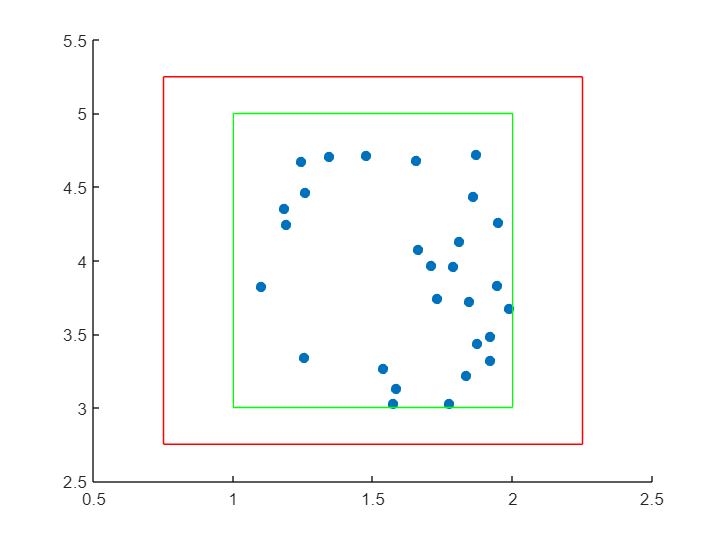

scatter(x, y, 'filled');
rectangle('Position', [1.0 3.0 1.0 2.0] ,  "EdgeColor",'g');
rectangle('Position', [0.75 2.75 1.5 2.5], "EdgeColor",'r');

The ratio of the remaining points to the original one is:

ratio = length(x) / N

ratio = 0.5600

Note $\textrm{rand}\left(\right)$ function distributes the data uniformly. Therefore, as we increase the number of *N* (try *N =1000* and *10000*), the number of remaining points gets closer to the ratio of the areas:


$$\frac{N\;\textrm{after}\;\textrm{removal}}{N\;\textrm{original}}=\frac{\textrm{area}\;\textrm{of}\;\textrm{the}\;\textrm{grean}\;\textrm{reactangle}}{\textrm{area}\;\textrm{of}\;\textrm{the}\;\textrm{red}\;\textrm{rectangle}}=\frac{1\ldotp 0\times 2\ldotp 0}{1\ldotp 5\times 2\ldotp 5}=0\ldotp 533$$


## Exercise 3

Try to redo exercise 2 with a for loop. You should plot** the same figure as exercise 2**.

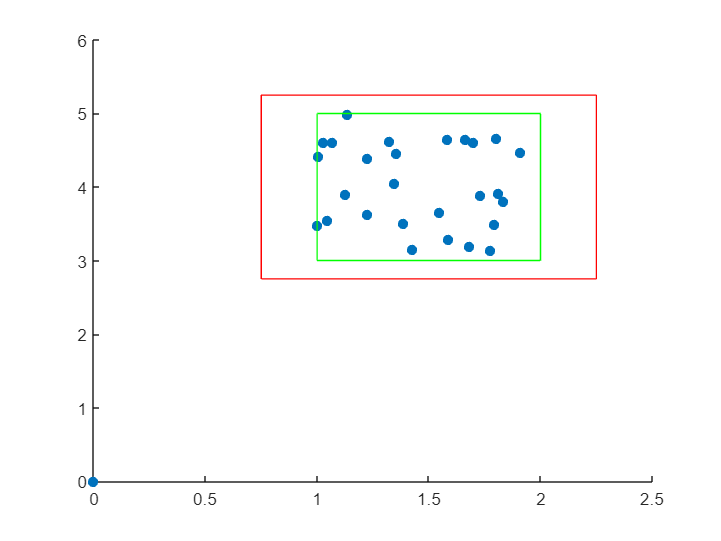

x  = rand(1, N);
y= rand(1, N);
x(:)= x(:) * 1.5 + 0.75;
y(:)= y(:) * 2.5 + 2.75;

n = 1;
x_inner = [];
y_inner = [];

for i=1:N
    if ( x(i) >= 1.0     &   x(i) <= 2.0     &    y(i) >= 3.0     &   y(i) <= 5.0)
            x_inner(i) = x(i);
            y_inner(i) = y(i);
            n = n+1;
    end
end

scatter(x_inner, y_inner, 'filled');
rectangle('Position', [1.0 3.0 1.0 2.0] ,  "EdgeColor",'g');
rectangle('Position', [0.75 2.75 1.5 2.5], "EdgeColor",'r');

ratio = (n)/N

ratio = 0.5600

Of note, vectors *x* and *y* changes in the beginning of this exercise. Therefore, the values of *ration* should be slightlly differnt compared to the previous exercise; however, both numbers shall tend to 0.533 as you increase *N.*